# 繪圖軟體應用 第11周(11/20) 

## CH08 底稿與函數的撰寫

函數主體和說明文字區之間要有一個空白行當界線

--------------------------------------------------------------

*function total = sum2(x,y)*

*% H1列*

*% 說*

*% 明*

*% 文 *

*% 字*

*% 區*

*% 函數的主體*

*total = x + y;*

*end*

-----------------------------------------------------------------

查閱m檔案的內容 : 使用type

### 函數 : sum2

----------------------------------------------------------------------

function total = sum2(x,y)

% H1列

% 說

% 明

% 文 

% 字

% 區

% 函數的主體

fprintf('nargin = %d, ',nargin)

fprintf('nargout = %d\n',nargout)

total = x + y;

end

----------------------------------------------------------------------

clear;clc
help sum2 % 查詢 m 檔案 sum2 的說明文字區

  H1列
  說
  明
  文 
  字
  區



type sum2 % 查詢 m 檔案 sum2 的內容


function total = sum2(x,y)
% H1列
% 說
% 明
% 文 
% 字
% 區

% 函數的主體
fprintf('nargin = %d, ',nargin)
fprintf('nargout = %d\n',nargout)
total = x + y;
end


t = sum2(4,5)

nargin = 2, nargout = 1


t = 9

s = sum2([5:10],[3:2:13])

nargin = 2, nargout = 1


s =      8    11    14    17    20    23


圓周長和圓面積

### 函數 : circle

----------------------------------------------------------------------

function [len,area] = circle(r)

%輸入半徑計算圓周長和圓面積

fprintf('nargin = %d, ',nargin)

fprintf('nargout = %d\n',nargout)

len = 2.*r.*pi; %圓周長

area = r.^2.*pi;%圓面積

end

----------------------------------------------------------------------

help circle % 查詢 m 檔案 circle 的說明文字區

 輸入半徑計算圓周長和圓面積



type circle % 查詢 m 檔案 circle 的內容


function [len,area] = circle(r)
%輸入半徑計算圓周長和圓面積

fprintf('nargin = %d, ',nargin)
fprintf('nargout = %d\n',nargout)
len = 2.*r.*pi; %圓周長
area = r.^2.*pi;%圓面積
end


[clen,carea] = circle(10) %半徑為10的圓周長和圓面積

nargin = 1, nargout = 2


clen = 62.8319

carea = 314.1593

[clen2,carea2] = circle([20,30]) %半徑為10的圓周長和圓面積

nargin = 1, nargout = 2


clen2 =   125.6637  188.4956


carea2 = 	1.0e+03 *

    1.2566    2.8274


## 引數的個數

- nargin : number of argument input 

- nargout : number of argument output 

----------------------------------------------------------------------

function [x1,x2,x3] = W1101(a1,a2)

fprintf('nargin = %d, ',nargin)

fprintf('nargout = %d\n',nargout)

if nargin == 1

    a2 = 0;

end

x1 = a1+a2;

x2 = a1-a2;

x3 = (a1+a2)/2;

end

----------------------------------------------------------------------

----------------------------------------------------------------------

function W1102(a,b)

fprintf('nargin = %d, ',nargin)

fprintf('nargout = %d\n',nargout)

if nargin == 1

    xx = 1:length(a);

    plot(xx,a)

else

    plot(a,b)

end

end

----------------------------------------------------------------------

clear;clc;clf
[x1,x2,x3] = W1101(3,5)

nargin = 2, nargout = 3


x1 = 8

x2 = -2

x3 = 4

[x1,x2,x3] = W1101(4)

nargin = 1, nargout = 3


x1 = 4

x2 = 4

x3 = 2

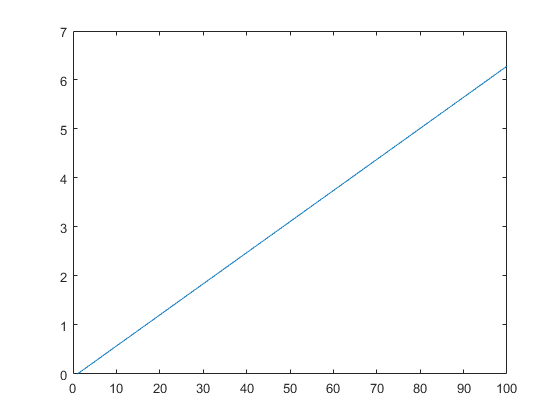

nargin = 1, nargout = 0



a = linspace(0,2*pi,100);
b = sin(2*a)./exp(a);
W1102(a)

nargin = 1, nargout = 0


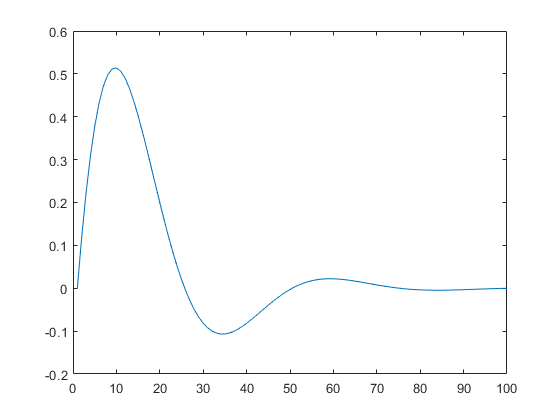

W1102(b)

nargin = 2, nargout = 0


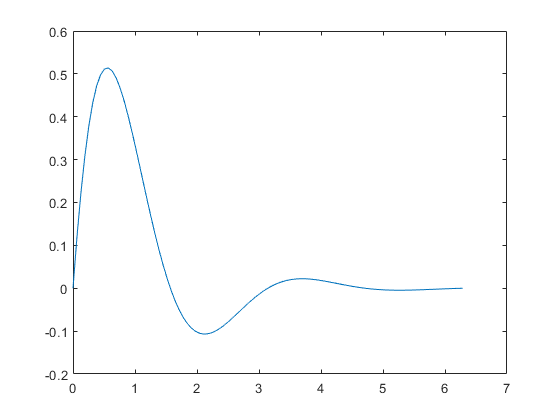

W1102(a,b)

## 宣告全域變數

----------------------------------------------------------------------

*function W1103(num)*

*global VAR;*

*VAR = VAR+num;*

*fprintf('在函數內，VAR = %d\n',VAR);*

*end*

*-----------------------------------------------------------------------*

global VAR
VAR = 10;
W1103(5)

在函數內，VAR = 15


W1103(5)

在函數內，VAR = 20


VAR

VAR = 20

## 子函數

一個M檔案最上方 : 主函數

其他函數 : 子函數

## 私有化目錄

- 不必設定路徑

- 不用把子函數撰寫在與主函數同一個M檔案內

## 保護程式碼

打開後是亂碼，但還是可執行

pcode 

## 匿名函數

一個引數

f = @ (x) sin(2*x).*exp(-x/2)

f = function_handle with value:
    @(x)sin(2*x).*exp(-x/2)


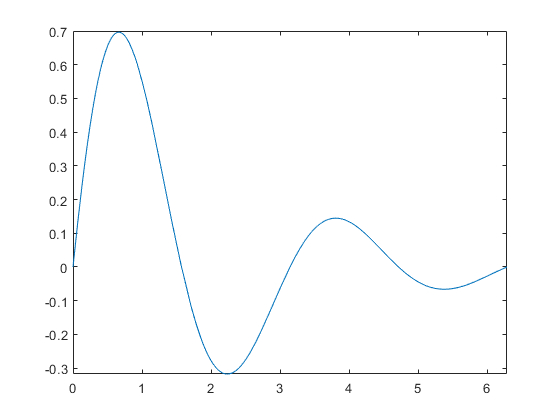

fplot(f,[0,2*pi])

兩個引數

g = @ (x,y) x./(x.^2+y.^2+1);
